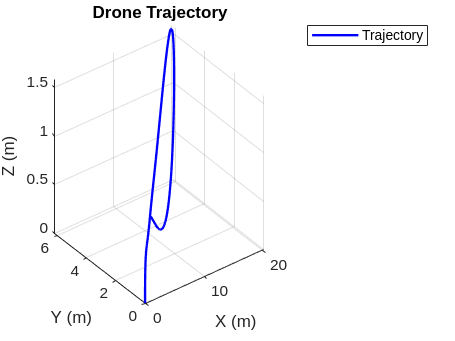

clc;
clear variables;
close all;


 % [x y z vx vy vz phi theta psi p q r]
% System params
m = 1.535;
g = 9.81;
Ixx = 0.029125;
Iyy = 0.029125;
Izz = 0.055225;
kt = 0.0;
kr = 0.0;

%Time variables
t_final = 9;
t_interval = 0.1;
time_span = 0:t_interval:t_final;

%State variables
state_all=[];
t_all=[];
current_state = zeros(1, 12);

%control input
u = [0; 0.0; 0.0; 0.0];
% n_steps = length(time);
% init_val_M = zeros(n_steps, 12);

%Set position values
x_ref = 10; y_ref = 3; z_ref = 2; 
yaw_ref = 0; 

Kp_pos = diag([0.4 0.4 0.4]);
Ki_pos = diag([0.0 0.0 0.0 ]);
Kd_pos = diag([0.01 0.01 0.465]);

Kp_ang = diag([0.4 0.4 0.4]);
Ki_ang = diag([0.0 0.0 0.0]);
Kd_ang = diag([0.1 0.1 0.465]);

e_pos_int = [0; 0; 0];
e_ang_int = [0; 0; 0];
e_pos_prev = [0; 0; 0];
e_ang_prev = [0; 0; 0];


for idx = 1:length(time_span)-1
    t_now = [time_span(idx), time_span(idx+1)];

    % State unpack
    x = current_state(1); y = current_state(2); z = current_state(3);
    vx = current_state(4); vy = current_state(5); vz = current_state(6);
    phi = current_state(7); theta = current_state(8); psi = current_state(9);
    p = current_state(10); q = current_state(11); r = current_state(12);

    %% --- PID for Position Control ---
    pos = [x; y; z];
    vel = [vx; vy; vz];
    ref_pos = [x_ref; y_ref; z_ref];

    e_pos = ref_pos - pos;
    e_dot_pos = (e_pos - e_pos_prev)/t_interval;
    e_pos_int = e_pos_int + e_pos;

    acc_cmd = Kp_pos * e_pos + Ki_pos * e_pos_int + Kd_pos * e_dot_pos;

    % Desired thrust
    T = m * (g + acc_cmd(3));

    % Desired orientation to achieve x, y motion
    theta_des = acc_cmd(1) / g;
    phi_des = -acc_cmd(2) / g;

    %% --- PID for Attitude Control ---
    e_ang = [phi_des - phi; theta_des - theta; yaw_ref - psi];
    e_dot_ang = (e_ang - e_ang_prev)/t_interval; 
    e_ang_int = e_ang_int + e_ang;

    tau = Kp_ang * e_ang + Ki_ang * e_ang_int + Kd_ang *e_dot_ang;

    % Input to dynamics
    u = [T, tau(1), tau(2), tau(3)];
    % u=[1.535*9.81,0.0,0.0,0.0];
    

    % Integrate dynamics
    [t, y_] = ode45(@(t, y) droneDynamics(t, y, u, m, g, Ixx, Iyy, Izz, kt, kr), t_now, current_state);
    state_all = [state_all; y_(1:end-1, :)]; % Exclude the last point to avoid duplication
    t_all = [t_all; t(1:end-1)];
    current_state = y_(end, :)';
    e_pos_prev = e_pos;
    e_ang_prev = e_ang;
end
% state_all = [state_all; current_state'];
% t_all = [t_all; tspan(end)];

%Plotting
figure;
plot3(state_all(:, 1), state_all(:, 2), state_all(:, 3), 'b', 'LineWidth', 1.5);
grid on;
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('Drone Trajectory');
legend('Trajectory');

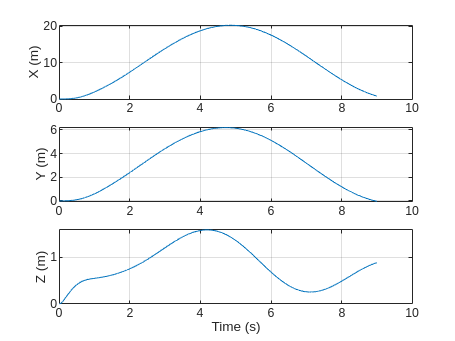


% figure;
% plot3(init_val_M(:,1), init_val_M(:,2), init_val_M(:,3), 'b', 'LineWidth', 1);
% xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
% title('3D Drone Trajectory (Full PID Control)');
% grid on; axis equal;
% 
% figure;
subplot(3,1,1); plot(t_all, state_all(:,1)); ylabel('X (m)'); grid on;
subplot(3,1,2); plot(t_all, state_all(:,2)); ylabel('Y (m)'); grid on;
subplot(3,1,3); plot(t_all, state_all(:,3)); ylabel('Z (m)'); xlabel('Time (s)'); grid on;

function dydt = droneDynamics(t, y, u,m,g,Ixx,Iyy,Izz,kt,kr)

    % State variables
    x_pos = y(1); y_pos = y(2); z_pos = y(3); % position
    vx = y(4); vy = y(5); vz = y(6); % velocity
    phi = y(7); theta = y(8); psi = y(9); % orientation
    p = y(10); q = y(11); r = y(12); % angular velocity

    T = u(1); % total thrust


    % Translational dynamics
    acc=[(1/(m))*((cos(phi)*cos(psi)*sin(theta)+sin(phi)*sin(psi))*T -kt*vx);
         (1/(m))*((cos(phi)*sin(psi)*sin(theta)-cos(psi)*sin(phi))*T -kt*vy) ;
         (1/(m))*((cos(phi)*cos(theta))*T - m*g - kt*vz)];
    
    % Rotational Dynamics
    ang_acc =[(1/Ixx)*(-kr*p -q*r*( Izz - Iyy)+u(2)) ;
              (1/Iyy)*(-kr*q-p*r*( Ixx - Izz)+u(3));
              (1/Izz)*(-kr*r-p*q*( Iyy - Ixx)+u(4))];

    % Derivatives
    dydt = zeros(12, 1);
    dydt(1:3) = [vx; vy; vz]; % position derivatives
    dydt(4:6) = acc;          % velocity derivatives
    dydt(7:9) = [p+(q*sin(phi)*tan(theta))+(r*cos(phi)*tan(theta));(q*cos(phi))-(r*sin(phi));(1/cos(theta))*(q*sin(phi)+r*cos(phi))]; % orientation derivatives
    dydt(10:12) = ang_acc; % angular velocity derivatives
end

